# Berkolaiko-Marzuola-Pelinovsky Quantum Graph Laplacian program

Computes the eigenvalues and eigenfunctions of the Laplace operator on a dumbbell graph

## Set up the graph structure and coordinates of the problem

LVec=[2 pi pi pi 2];
nX=round(10*LVec);
[source,target]=BMPTemplate();
Phi = quantumGraph(source,target,LVec,'nxVec',nX);

## Calculate and plot the secular determinant of the quantum graph

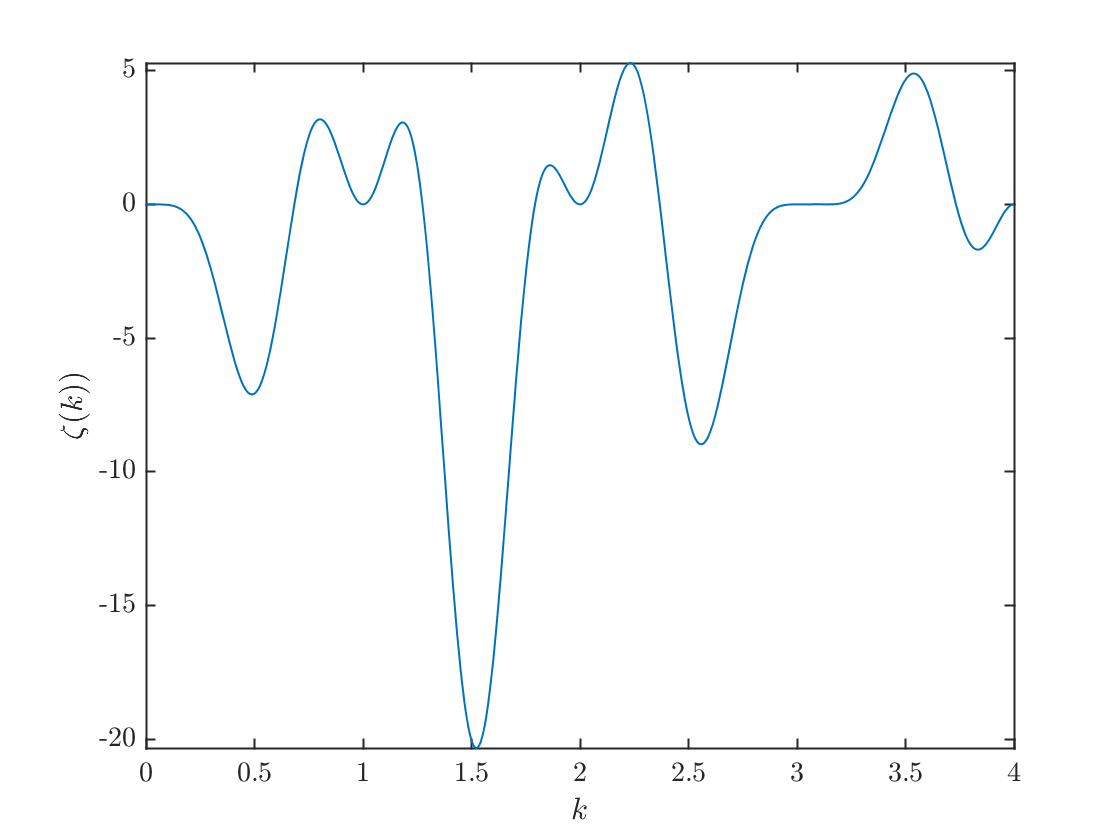

f = secularDet(Phi);
fplot(f,[0 4])
xlabel('$k$')
ylabel('$\zeta(k))$')

## Set up coordinates on which to plot the solutions

Note that the user has to create the plotting function. Note further, you could also add this by adding the key-value pair 'PlotCoordinateFcn',@dumbbellPlotCoords to the above line of code Phi = quantumGraph(...

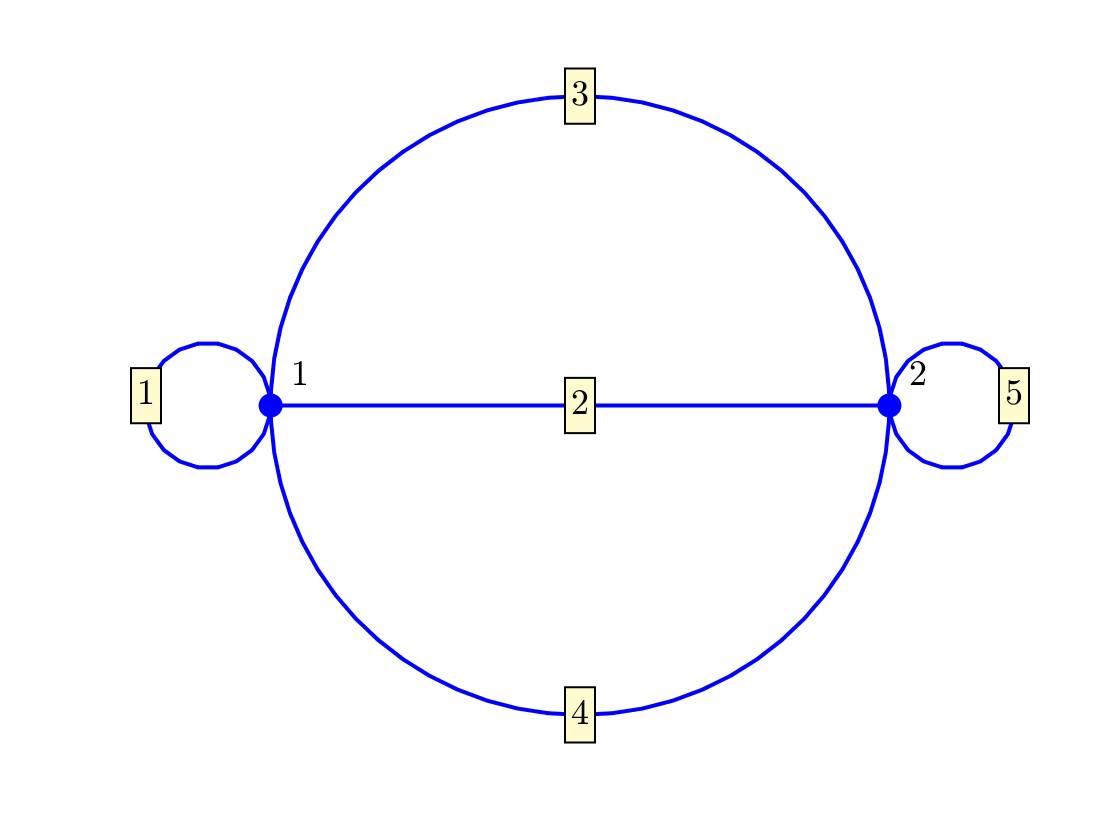

Phi.addPlotCoords(@BMPPlotCoords);
Phi.plot('layout')

drawnow

## Construct the Laplacian and calculate its eigenvalues and eigenvectors

A little cleanup needed because the null eigenvalue is sometimes calculated as positive and sometimes as negative and this screws up the sorting.

[V,lambda]=eig(Phi);
[singles,doubles,~]=separateEigs(lambda); % No triple eigenvalue unless handle and hoops resonant

nToPlot=4;

## Plot the first few multiplicity-one eigenfunctions

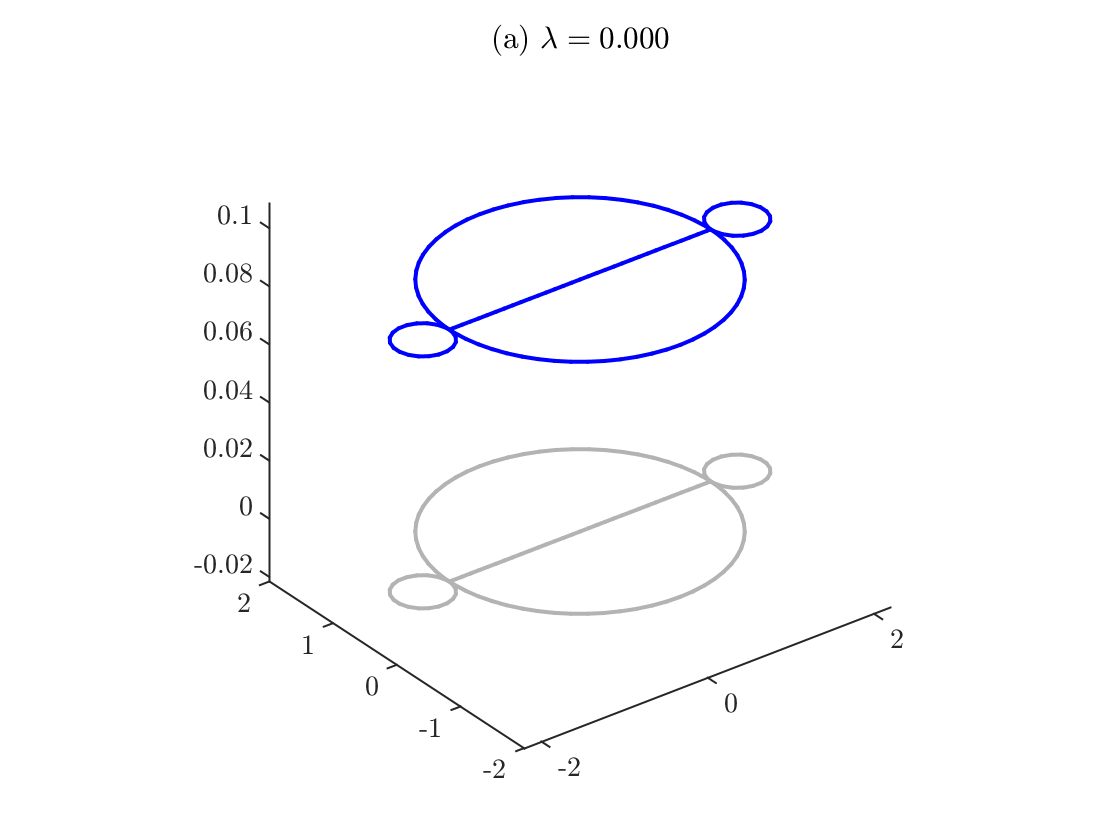

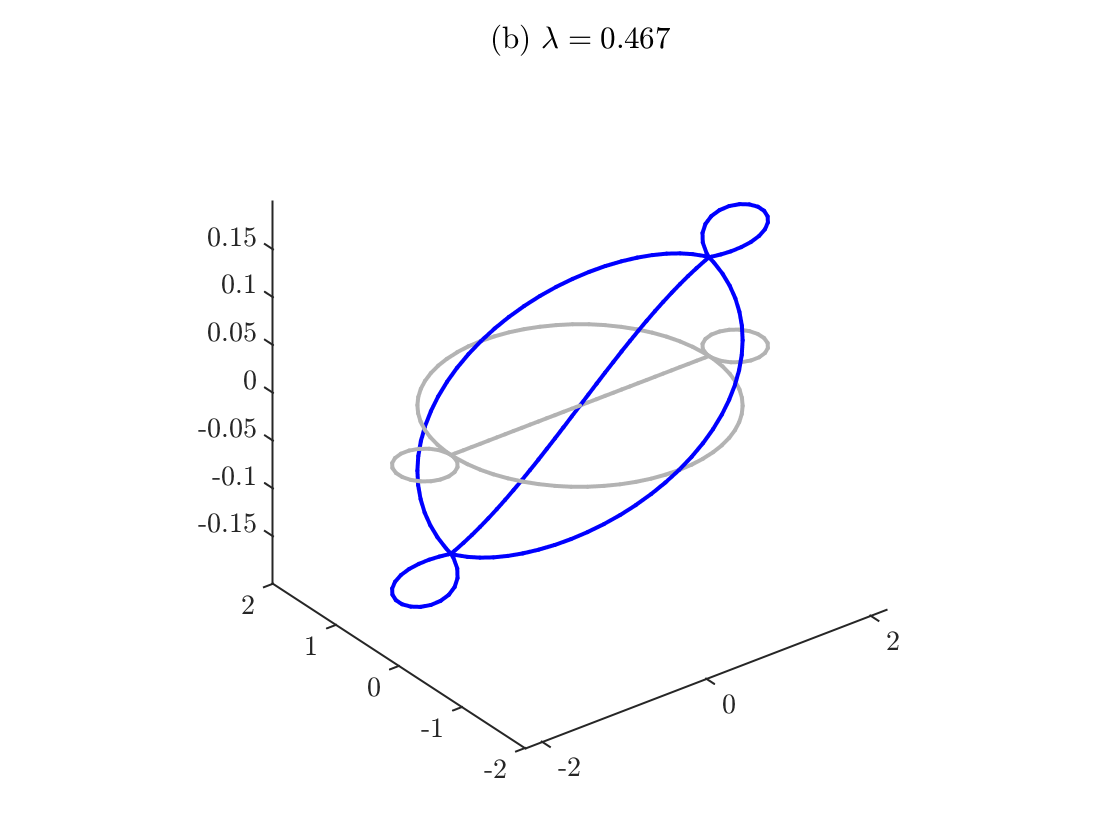

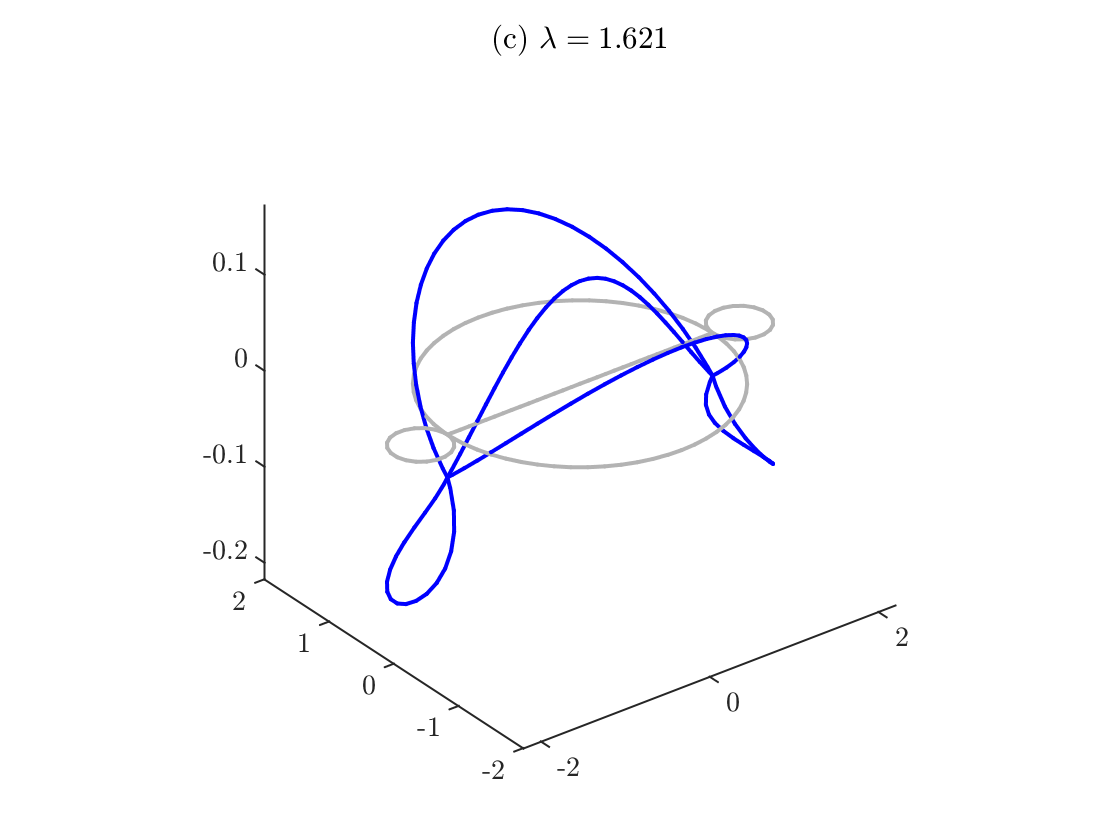

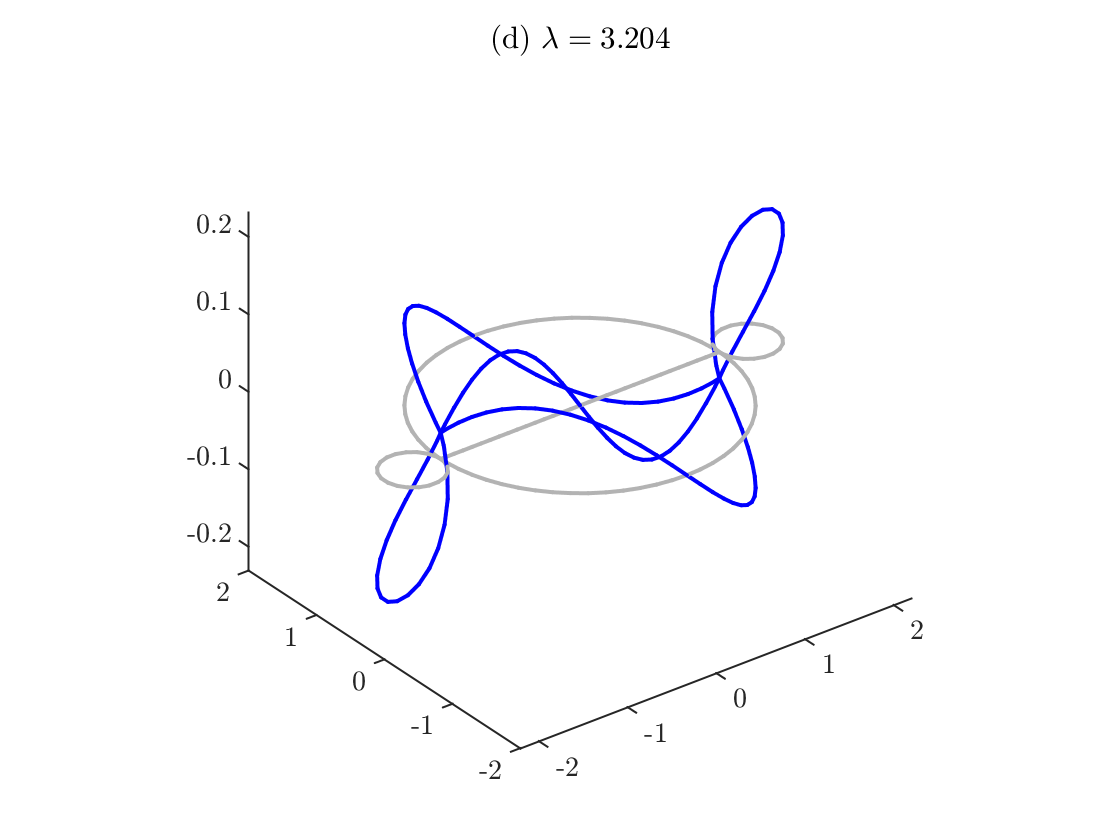

for k=1:nToPlot
    figure
    Phi.plot(V(:,singles(k)))
    title(sprintf('(%s) $\\lambda = %0.3f$', letter(k),lambda(singles(k))));
end

## Plot the first few multiplicity-two eigenfunctions

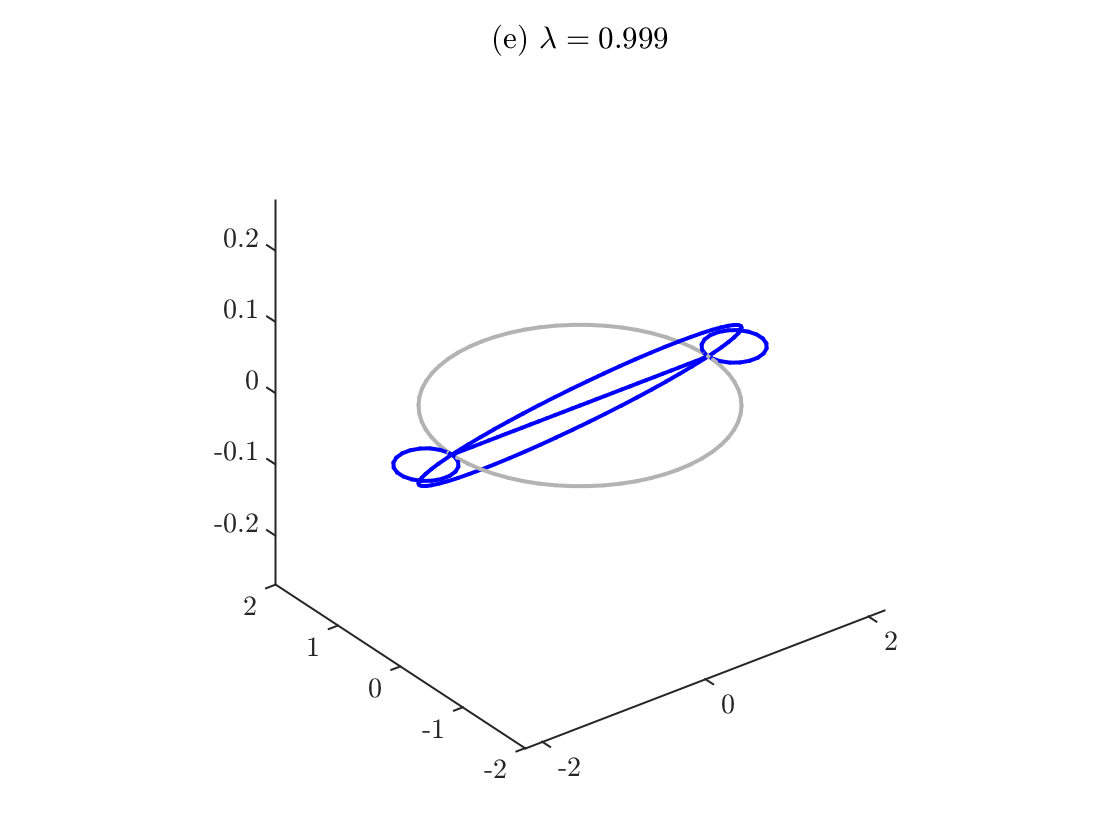

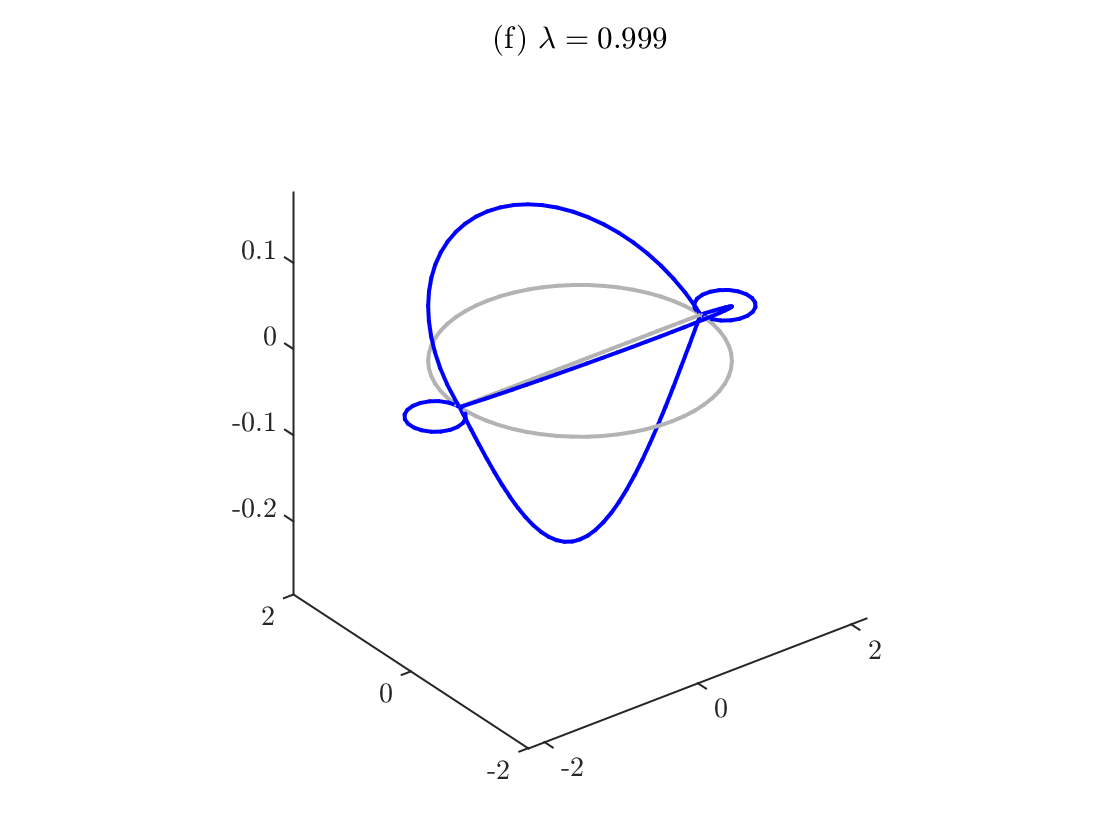

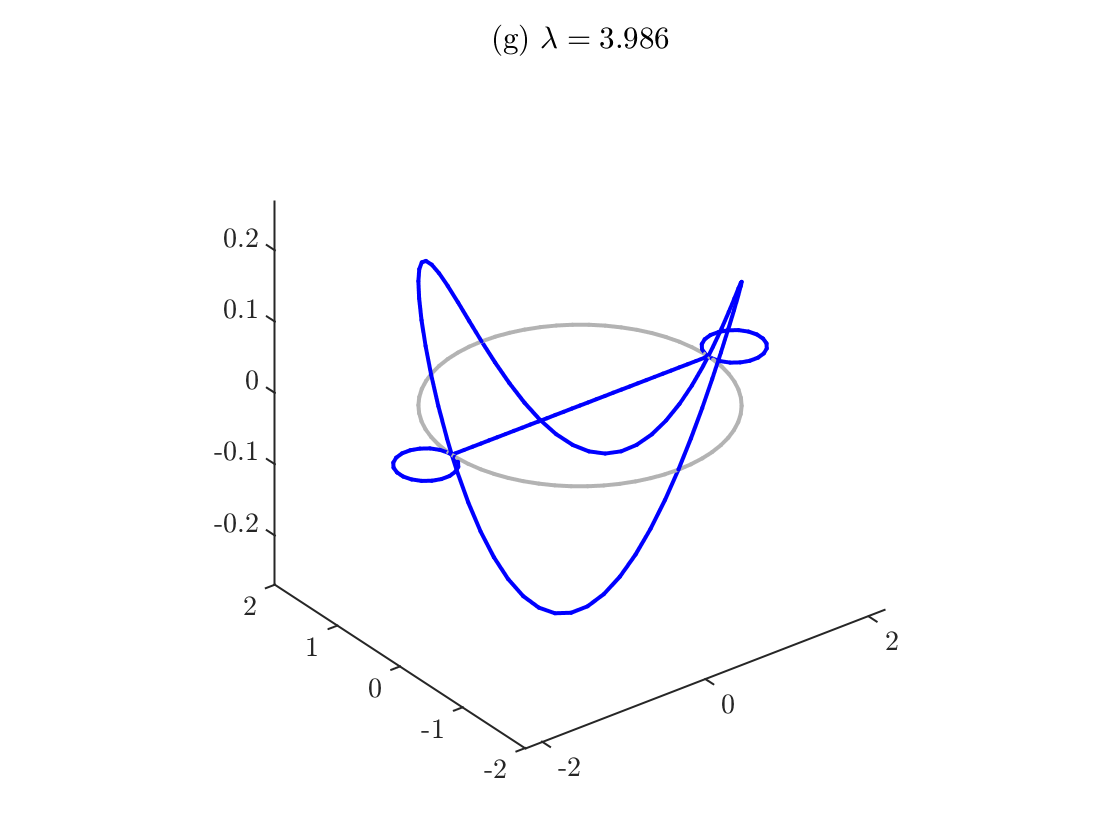

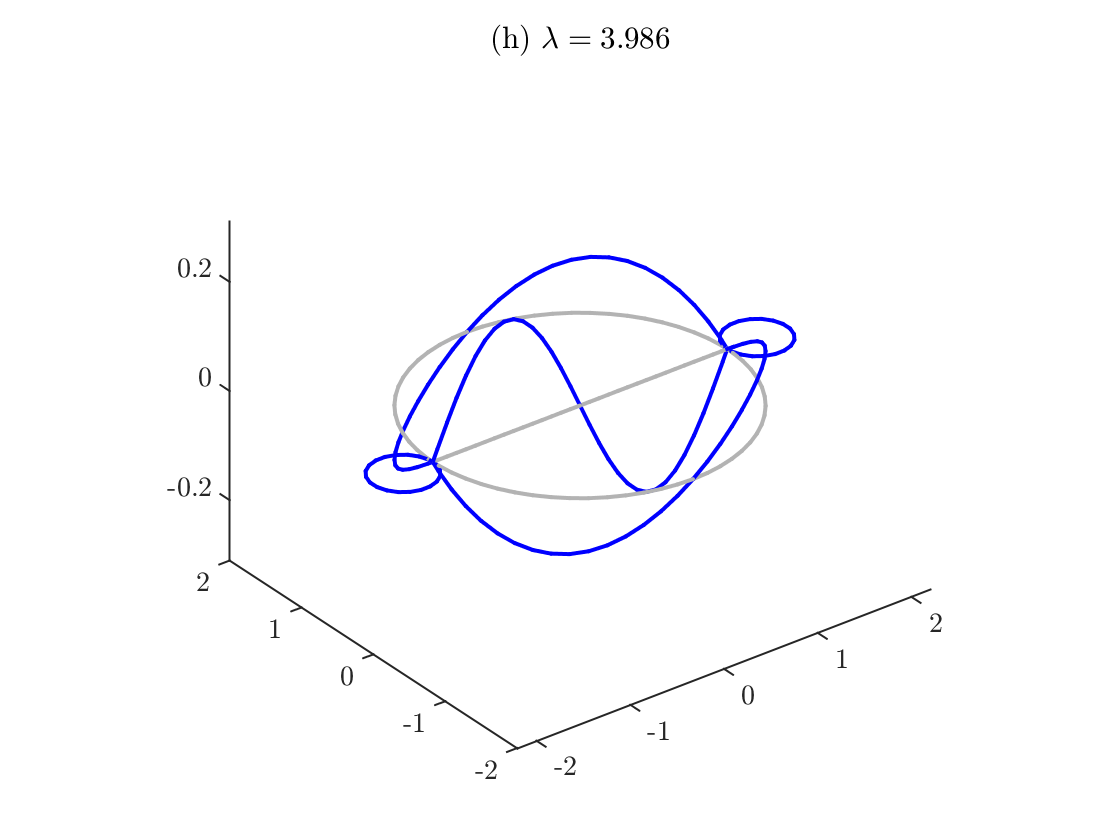

j=nToPlot;
if ~isempty(doubles)
    nx=Phi.nx;
    for k=1:nToPlot/2
        vv=BMPResolveDoubles(V,doubles(k),nXVec);
        figure
        j=j+1;
        Phi.plot(vv{1})
        title(sprintf('(%s) $\\lambda = %0.3f$', letter(j), lambda(doubles(k))));
        figure
        j=j+1;
        Phi.plot(vv{2})
        title(sprintf('(%s) $\\lambda = %0.3f$', letter(j), lambda(doubles(k))));
    end
end